# **Implementación EC en matlab de modulación digital y analógica**

Andrés Fernando Jerez Medina - 2190416

Jorge Eduardo Angarita Perez - 2190427

Sergio Sebastián Oliveros Sepulveda - 2190396

## **Punto 1**

Se implementan las señales x(t) y y(t) de la envolvente compleja para una modulación 8PSK con un tiempo de 0.05 segundos, para transmitir la secuencia de bits 101100111001 (asumiendo que se transmiten de derecha a izquierda).

Parámetros

Ac = 1;         %Amplitud Portadora
Tb = 0.05;      %Tiempo de Bit
sps = 8;      %Muestras por símbolo (Personalizado by us)
Ts = Tb/sps;    %Tiempo de Muestreo
L = 3;          %# de Bits que conforman un Símbolo
fc = 1/(Ts*8); %Frecuencia de portadora 

En este caso, se usa un valor de amplitud de 1 dado que se va a realizar la modulación en fase, un valor de sps de 8 muestras por simbolo y la cantidad de bits que se agrupan será de 3, porque $M=2^L \;$ y $M=8$.

El tiempo de muestreo usado es el tiempo de bit dividido en la cantidad de muestras por simbolo, de esa manera se podrá observar las señales perfectamente. Y finalmente, la frecuencia de portadora se escogió como 8 veces la frecuencia de muestreo.

Bits

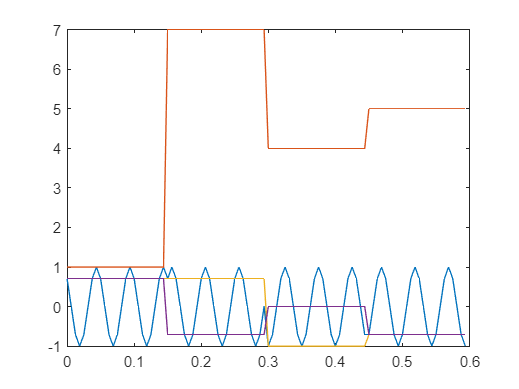

bits = [1 0 1 1 0 0 1 1 1 0 0 1];       %Bits de llegada
NBit = length(bits);                    %Número de Bits 
t = 0:Ts:Tb*NBit-Ts;                    %Tiempo
Nsamples = NBit*sps;                    %Número de Muestras
n = 1:Nsamples;                         %Muestras
sym = bit2sym(bits,L);
m_t = vect2samp(bits,sps);
sym_t = vect2samp(sym, sps*L);       
g_t = Ac*exp(1j*sym_t*pi/4);            %Envolvente compleja
x_t = real(g_t);                        %Componente en Fase
y_t = imag(g_t);                        %Componente en cuadratura
s_t = x_t*cos(2*pi*fc*t)-y_t*sin(2*pi*fc*t);     %Señal Modulada

En la gráfica se puede observar las señales en el dominio del tiempo de la parte real de la envolvente compleja x(t9, la parte imaginaria de la envolvence compleja y(t), la señal modulada s(t) y el mensaje con sus valores en decimal.

Funciones:

function [sym, bitOrder] = bit2sym(bits, L) %Para generar los símbolos
    NBit = length(bits);
    Power2 = 2.^(L-1:-1:0);
    Nsteps = NBit/L;
    sym = zeros(1,Nsteps);
    for i = 1:Nsteps
        BitAct = bits(end-i*L+1:end-(i-1)*L);
        bit((i-1))
        sym(i) = dot(Power2,BitAct);
    end
end

function m = vect2samp(vect, sps) %Para pasar de los bits al tiempo muestreado
    Nvect = length(vect);
    m = zeros(1, sps*Nvect);
    for i = 1:Nvect
        m((i-1)*sps+1:i*sps) = vect(i);
    end
end